clc;
clear all;
close all;

Init

% % number of tx and rx antennas
numTx = [2,4,8,16,32,64,128];
numRx = [2,4,8,16,32,64,128];

% modulation order (16-QAM)
M = 16;

% number of transmitted symbols (the larger the more precise the results will be)
num_symbols = 6144*max(numTx); 

% generate random symbols 
symbols = randi([0 M-1], 1, num_symbols);

% points to plot
points = 20;
% min and max value for snr
snr_min = 15;
snr_max = 35;
% generates an array of SNR values in the range [snr_min, snr_max] with a length equal to points
snr=linspace(snr_min,snr_max,points);

% Energy per symbol
Es = sum(abs(symbols).^2) / length(symbols);
% Energy per bit
Eb = Es / log2(M);
% Convert SNR to Eb/N0
eb_n0 = snr - 10 * log10(Eb);
% Min and Max Eb/N0
eb_n0_min = min(eb_n0);
eb_n0_max = max(eb_n0);

Scenario 1 : 2x2 Tx-Rx

% Compute the ber
[ber_zf_2x2, ber_vblast_2x2] = com_sys(numTx(1), numRx(1), symbols, M, eb_n0);

ans = 5

ans = 10

ans = 15

ans = 20

ans = 25

ans = 30

ans = 35

ans = 40

ans = 45

ans = 50

ans = 55

ans = 60

ans = 65

ans = 70

ans = 75

ans = 80

ans = 85

ans = 90

ans = 95

ans = 100

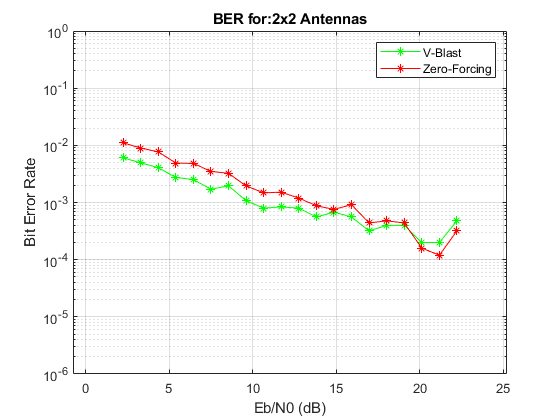


% plot the results
semilogy(eb_n0,ber_vblast_2x2,'g-*');
hold on;
semilogy(eb_n0,ber_zf_2x2,'r-*');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^0])
title({ strcat('BER for: ', num2str(numTx(1)), 'x' , num2str(numRx(1)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 2: 4x4 Tx-Rx

% Compute the ber
[ber_zf_4x4, ber_vblast_4x4] = com_sys(numTx(2), numRx(2), symbols, M, eb_n0);

ans = 5

ans = 10

ans = 15

ans = 20

ans = 25

ans = 30

ans = 35

ans = 40

ans = 45

ans = 50

ans = 55

ans = 60

ans = 65

ans = 70

ans = 75

ans = 80

ans = 85

ans = 90

ans = 95

ans = 100

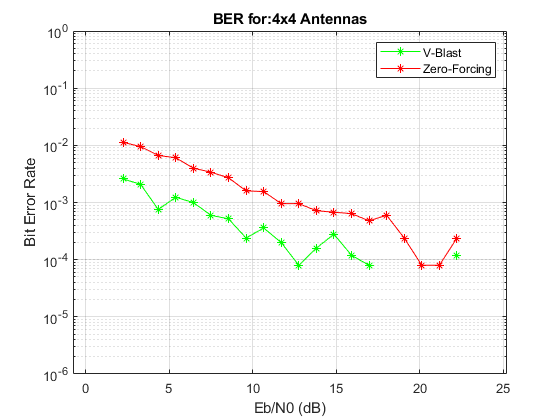


% plot the results
semilogy(eb_n0,ber_vblast_4x4,'g-*');
hold on
semilogy(eb_n0,ber_zf_4x4,'r-*');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^0])
title({ strcat('BER for: ', num2str(numTx(2)), 'x' , num2str(numRx(2)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 3: 8x8 Tx-Rx

% Compute the ber
[ber_zf_8x8, ber_vblast_8x8] = com_sys(numTx(3), numRx(3), symbols, M, eb_n0);

ans = 5

ans = 10

ans = 15

ans = 20

ans = 25

ans = 30

ans = 35

ans = 40

ans = 45

ans = 50

ans = 55

ans = 60

ans = 65

ans = 70

ans = 75

ans = 80

ans = 85

ans = 90

ans = 95

ans = 100

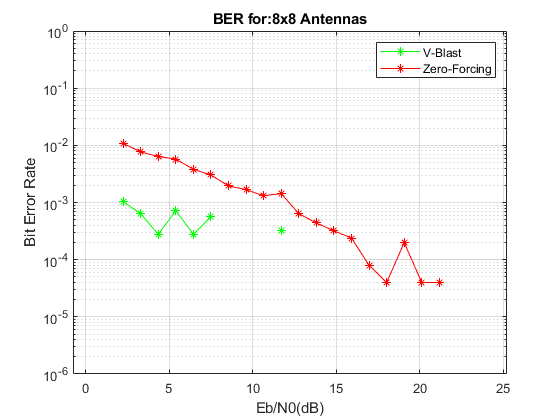


% plot the results
semilogy(eb_n0,ber_vblast_8x8,'g-*');
hold on;
semilogy(eb_n0,ber_zf_8x8,'r-*');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^0])
title({ strcat('BER for: ', num2str(numTx(3)), 'x' , num2str(numRx(3)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0(dB)');
ylabel('Bit Error Rate');
grid on

Scenario 4: 16x16 Tx-Rx

% Compute the ber
[ber_zf_16x16, ber_vblast_16x16] = com_sys(numTx(4), numRx(4), symbols, M, eb_n0);

ans = 5

ans = 10


% plot the results
semilogy(eb_n0,ber_vblast_16x16,'g-*');
hold on;
semilogy(eb_n0,ber_zf_16x16,'r-*');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6 10^0]); 
title({ strcat('BER for: ', num2str(numTx(4)), 'x' , num2str(numRx(4)), ' Antennas')})
legend('V-Blast', 'Zero-Forcing');
xlabel('Eb/N0(dB)');
ylabel('Bit Error Rate');
grid on

Scenario 5: 32x32 Tx-Rx

% Compute the ber
[ber_zf_32x32, ber_vblast_32x32] = com_sys(numTx(5), numRx(5), symbols, M, eb_n0);

% plot the results
semilogy(eb_n0,ber_vblast_32x32,'g-*');
hold on;
semilogy(eb_n0,ber_zf_32x32,'r-*');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6 10^0])
title({ strcat('BER for: ', num2str(numTx(5)), 'x' , num2str(numRx(5)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0(dB)');
ylabel('Bit Error Rate');
grid on

Scenario 6: 64x64 Tx-Rx

% Compute the ber
[ber_zf_64x64, ber_vblast_64x64] = com_sys(numTx(6), numRx(6), symbols, M, eb_n0);

% plot the results
semilogy(eb_n0,ber_vblast_64x64,'g-*');
hold on;
semilogy(eb_n0,ber_zf_64x64,'r-*');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6 10^0])
title({ strcat('BER for: ', num2str(numTx(6)), 'x' , num2str(numRx(6)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0(dB)');
ylabel('Bit Error Rate');
grid on

Scenario 7: 128x128 Tx-Rx

% Compute the ber
[ber_zf_128x128, ber_vblast_128x128] = com_sys(numTx(7), numRx(7), symbols, M, eb_n0);

% plot the results
semilogy(eb_n0,ber_vblast_128x128,'g-*');
hold on;
semilogy(eb_n0,ber_zf_128x128,'r-*');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-7 10^0])
title({ strcat('BER for: ', num2str(numTx(7)), 'x' , num2str(numRx(8)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0(dB)');
ylabel('Bit Error Rate');
grid on